% Get the directory path where the csv files are located
dir_path = '/Users/ohadformanair/Downloads/traces';

% Read the csv files
s11_atten = readtable(fullfile(dir_path, '1.csv'));

s22_atten = readtable(fullfile(dir_path, '2.csv'));

s12_atten = readtable(fullfile(dir_path, '3.csv'));

s12_lpf = readtable(fullfile(dir_path, '4.csv'));

s11_lpf = readtable(fullfile(dir_path, '5.csv'));

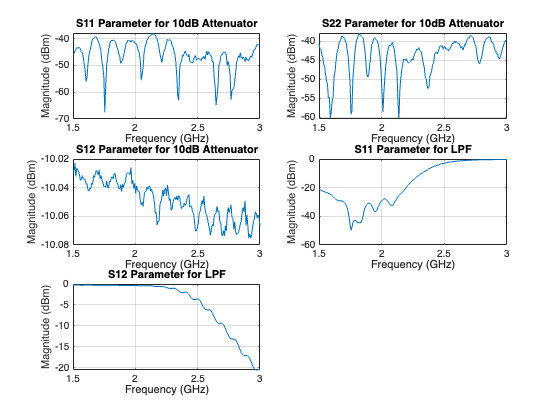


% Extract the frequency and data columns, and convert frequency to GHz
freq_s11 = s11_atten{:, 'Frequency'} / 1e9;
s11 = s11_atten{:, 'FormattedData'};
freq_s22 = s22_atten{:, 'Frequency'} / 1e9;
s22 = s22_atten{:, 'FormattedData'};
freq_s12_atten = s12_atten{:, 'Frequency'} / 1e9;
s12_atten = s12_atten{:, 'FormattedData'};
freq_s12_lpf = s12_lpf{:, 'Frequency'} / 1e9;
s12_lpf = s12_lpf{:, 'FormattedData'};
freq_s11_lpf = s11_lpf{:, 'Frequency'} / 1e9;
s11_lpf = s11_lpf{:, 'FormattedData'};

% Plot the data
figure;
subplot(3,2,1);
plot(freq_s11, s11);
title('S11 Parameter for 10dB Attenuator');
xlabel('Frequency (GHz)');
ylabel('Magnitude (dBm)');
grid on;

subplot(3,2,2);
plot(freq_s22, s22);
title('S22 Parameter for 10dB Attenuator');
xlabel('Frequency (GHz)');
ylabel('Magnitude (dBm)');
grid on;

subplot(3,2,3);
plot(freq_s12_atten, s12_atten);
title('S12 Parameter for 10dB Attenuator');
xlabel('Frequency (GHz)');
ylabel('Magnitude (dBm)');
grid on;

subplot(3,2,4);
plot(freq_s11_lpf, s11_lpf);
title('S11 Parameter for LPF');
xlabel('Frequency (GHz)');
ylabel('Magnitude (dBm)');
grid on;

subplot(3,2,5);
plot(freq_s12_lpf, s12_lpf);
title('S12 Parameter for LPF');
xlabel('Frequency (GHz)');
ylabel('Magnitude (dBm)');
grid on;
saveas(gcf, fullfile(dir_path, 'myfigure.png'));